# **PHẦN 1: CẮT MẶT VÀ CHUẨN HÓA DỮ LIỆU (CHỈ CHẠY 1 LẦN)**

sourceDir = 'DLmetadata';       % Thư mục chứa 28 folder của bạn
processedDir = 'DataClean'; % Thư mục chứa ảnh sau khi xử lý

% Khởi tạo bộ dò khuôn mặt
faceDetector = vision.CascadeObjectDetector();
imds = imageDatastore(sourceDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Lấy danh sách đường dẫn file và nhãn tương ứng
allFiles = imds.Files;
allLabels = imds.Labels;

fprintf('Bắt đầu cắt mặt... Vui lòng chờ.\n');

Bắt đầu cắt mặt... Vui lòng chờ.



for i = 1:numel(allFiles)
    img = readimage(imds, i); % Đọc ảnh thứ i
    bbox = faceDetector(img); % Tìm khuôn mặt
    
    if ~isempty(bbox)
        % Lấy khuôn mặt lớn nhất (tránh lấy nhầm chi tiết nhỏ trong nền)
        [~, maxIdx] = max(bbox(:,3));
        faceImg = imcrop(img, bbox(maxIdx, :));
        
        % 1. Xử lý ảnh màu (Đồng nhất 3 kênh để tránh lỗi 3rd dimension)
        if size(faceImg, 3) == 1
            faceImg = cat(3, faceImg, faceImg, faceImg);
        elseif size(faceImg, 3) > 3
            faceImg = faceImg(:,:,1:3); % Loại bỏ kênh Alpha nếu có
        end
        
        % 2. Resize chuẩn SqueezeNet
        faceImg = imresize(faceImg, [227 227]);
        
        % 3. Lưu ảnh vào thư mục nhãn tương ứng
        currentLabel = char(allLabels(i));
        destDir = fullfile(processedDir, currentLabel);
        if ~exist(destDir, 'dir'), mkdir(destDir); end
        
        [~, name, ext] = fileparts(allFiles{i});
        imwrite(faceImg, fullfile(destDir, [name ext]));
    end
    
    % Hiển thị tiến độ mỗi 50 ảnh
    if mod(i, 50) == 0
        fprintf('Đã xử lý %d / %d ảnh...\n', i, numel(allFiles));
    end
end

Đã xử lý 50 / 535 ảnh...
Đã xử lý 100 / 535 ảnh...
Đã xử lý 150 / 535 ảnh...
Đã xử lý 200 / 535 ảnh...
Đã xử lý 250 / 535 ảnh...
Đã xử lý 300 / 535 ảnh...
Đã xử lý 350 / 535 ảnh...
Đã xử lý 400 / 535 ảnh...
Đã xử lý 450 / 535 ảnh...
Đã xử lý 500 / 535 ảnh...


fprintf('Hoàn thành! Ảnh sạch nằm trong: %s\n', processedDir);

Hoàn thành! Ảnh sạch nằm trong: DataClean


## **THÊM NHIỄU ĐỂ TẠO THÊM ẢNH**

% --- BƯỚC 2: THÊM NHIỄU (Đặt đoạn code này tại đây) ---
% Mục tiêu: Tạo ra biến thể của ảnh đã cắt mặt để tăng gấp đôi dữ liệu sạch.
cleanImds = imageDatastore(processedDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
allFiles = cleanImds.Files;

fprintf('Bắt đầu thêm nhiễu cho ảnh...\n');

Bắt đầu thêm nhiễu cho ảnh...


for i = 1:numel(allFiles)
    img = imread(allFiles{i});
    % Thêm nhiễu Gaussian cực nhẹ
    noiseImg = imnoise(img, 'gaussian', 0, 0.005); 
    
    [path, name, ext] = fileparts(allFiles{i});
    newName = fullfile(path, [name '_noise' ext]);
    
    % Kiểm tra nếu file chưa tồn tại thì mới ghi để tránh ghi đè nhiều lần
    if ~exist(newName, 'file')
        imwrite(noiseImg, newName);
    end
end
fprintf('Đã nhân đôi số lượng ảnh trong thư mục DataClean!\n');

Đã nhân đôi số lượng ảnh trong thư mục DataClean!


## PHẦN 2: TĂNG CƯỜNG VÀ CHIA DỮ LIỆU ĐỂ ĐƯA VÀO APP

Nạp lại dữ liệu đã sạch

imdsClean = imageDatastore(processedDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Chia 70% train, 30% validation
[imdsTrain, imdsVal] = splitEachLabel(imdsClean, 0.7, 'randomized');

% Thiết lập tăng cường ảnh dành riêng cho khuôn mặt
imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-20 20], ...   % Xoay nhẹ (mặt người không nên xoay quá nhiều)
    'RandXReflection', true, ...    % Lật trái phải (rất tốt cho nhận diện mặt)
    'RandXTranslation', [-10 10], ... % Dịch chuyển nhẹ
    'RandYTranslation', [-10 10]);
% Tạo Datastore cuối cùng cho SqueezeNet
augTrain = augmentedImageDatastore([227 227 3], imdsTrain, 'DataAugmentation', imageAugmenter);
augVal = augmentedImageDatastore([227 227 3], imdsVal); % Validation không cần tăng cường

fprintf('Dữ liệu đã sẵn sàng trong Workspace (augTrain, augVal).\n');

Dữ liệu đã sẵn sàng trong Workspace (augTrain, augVal).


# **Create and Train a Deep Learning Model**

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `lgraph`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 29-Dec-2025 09:25:08

## Load Training Setup Data

Load the data used to set up training. The training setup file contains the parameters for network initialization and the training and validation data. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("D:\20251\SqueezeNet.mat");

## Import Data

Import training and validation data.

dsTrain = trainingSetup.dsTrain;
dsValidation = trainingSetup.dsValidation;

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",5e-05,...
    "MaxEpochs",100,...
    "MiniBatchSize",8,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",25,...
    "Plots","training-progress",...
    "ValidationData",dsValidation);

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([227 227 3],"Name","data","Mean",trainingSetup.data.Mean)
    convolution2dLayer([3 3],64,"Name","conv1","Stride",[2 2],"Bias",trainingSetup.conv1.Bias,"Weights",trainingSetup.conv1.Weights)
    reluLayer("Name","relu_conv1")
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    convolution2dLayer([1 1],16,"Name","fire2-squeeze1x1","Bias",trainingSetup.fire2_squeeze1x1.Bias,"Weights",trainingSetup.fire2_squeeze1x1.Weights)
    reluLayer("Name","fire2-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","fire2-expand1x1","Bias",trainingSetup.fire2_expand1x1.Bias,"Weights",trainingSetup.fire2_expand1x1.Weights)
    reluLayer("Name","fire2-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","fire2-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire2_expand3x3.Bias,"Weights",trainingSetup.fire2_expand3x3.Weights)
    reluLayer("Name","fire2-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire2-concat")
    convolution2dLayer([1 1],16,"Name","fire3-squeeze1x1","Bias",trainingSetup.fire3_squeeze1x1.Bias,"Weights",trainingSetup.fire3_squeeze1x1.Weights)
    reluLayer("Name","fire3-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","fire3-expand1x1","Bias",trainingSetup.fire3_expand1x1.Bias,"Weights",trainingSetup.fire3_expand1x1.Weights)
    reluLayer("Name","fire3-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","fire3-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire3_expand3x3.Bias,"Weights",trainingSetup.fire3_expand3x3.Weights)
    reluLayer("Name","fire3-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire3-concat")
    maxPooling2dLayer([3 3],"Name","pool3","Padding",[0 1 0 1],"Stride",[2 2])
    convolution2dLayer([1 1],32,"Name","fire4-squeeze1x1","Bias",trainingSetup.fire4_squeeze1x1.Bias,"Weights",trainingSetup.fire4_squeeze1x1.Weights)
    reluLayer("Name","fire4-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","fire4-expand1x1","Bias",trainingSetup.fire4_expand1x1.Bias,"Weights",trainingSetup.fire4_expand1x1.Weights)
    reluLayer("Name","fire4-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","fire4-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire4_expand3x3.Bias,"Weights",trainingSetup.fire4_expand3x3.Weights)
    reluLayer("Name","fire4-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire4-concat")
    convolution2dLayer([1 1],32,"Name","fire5-squeeze1x1","Bias",trainingSetup.fire5_squeeze1x1.Bias,"Weights",trainingSetup.fire5_squeeze1x1.Weights)
    reluLayer("Name","fire5-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","fire5-expand1x1","Bias",trainingSetup.fire5_expand1x1.Bias,"Weights",trainingSetup.fire5_expand1x1.Weights)
    reluLayer("Name","fire5-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","fire5-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire5_expand3x3.Bias,"Weights",trainingSetup.fire5_expand3x3.Weights)
    reluLayer("Name","fire5-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire5-concat")
    maxPooling2dLayer([3 3],"Name","pool5","Padding",[0 1 0 1],"Stride",[2 2])
    convolution2dLayer([1 1],48,"Name","fire6-squeeze1x1","Bias",trainingSetup.fire6_squeeze1x1.Bias,"Weights",trainingSetup.fire6_squeeze1x1.Weights)
    reluLayer("Name","fire6-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","fire6-expand1x1","Bias",trainingSetup.fire6_expand1x1.Bias,"Weights",trainingSetup.fire6_expand1x1.Weights)
    reluLayer("Name","fire6-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],192,"Name","fire6-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire6_expand3x3.Bias,"Weights",trainingSetup.fire6_expand3x3.Weights)
    reluLayer("Name","fire6-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire6-concat")
    convolution2dLayer([1 1],48,"Name","fire7-squeeze1x1","Bias",trainingSetup.fire7_squeeze1x1.Bias,"Weights",trainingSetup.fire7_squeeze1x1.Weights)
    reluLayer("Name","fire7-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","fire7-expand1x1","Bias",trainingSetup.fire7_expand1x1.Bias,"Weights",trainingSetup.fire7_expand1x1.Weights)
    reluLayer("Name","fire7-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],192,"Name","fire7-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire7_expand3x3.Bias,"Weights",trainingSetup.fire7_expand3x3.Weights)
    reluLayer("Name","fire7-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire7-concat")
    convolution2dLayer([1 1],64,"Name","fire8-squeeze1x1","BiasLearnRateFactor",5,"WeightLearnRateFactor",5)
    reluLayer("Name","fire8-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","fire8-expand1x1","Bias",trainingSetup.fire8_expand1x1.Bias,"Weights",trainingSetup.fire8_expand1x1.Weights)
    reluLayer("Name","fire8-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","fire8-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire8_expand3x3.Bias,"Weights",trainingSetup.fire8_expand3x3.Weights)
    reluLayer("Name","fire8-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire8-concat")
    convolution2dLayer([1 1],64,"Name","fire9-squeeze1x1","BiasLearnRateFactor",5,"WeightLearnRateFactor",5)
    reluLayer("Name","fire9-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","fire9-expand1x1","Bias",trainingSetup.fire9_expand1x1.Bias,"Weights",trainingSetup.fire9_expand1x1.Weights)
    reluLayer("Name","fire9-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","fire9-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire9_expand3x3.Bias,"Weights",trainingSetup.fire9_expand3x3.Weights)
    reluLayer("Name","fire9-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire9-concat")
    dropoutLayer(0.5,"Name","drop9")
    convolution2dLayer([1 1],28,"Name","conv10","BiasLearnRateFactor",20,"WeightLearnRateFactor",20)
    reluLayer("Name","relu_conv10")
    globalAveragePooling2dLayer("Name","pool10")
    softmaxLayer("Name","prob")
    classificationLayer("Name","ClassificationLayer_predictions")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"fire2-relu_squeeze1x1","fire2-expand1x1");
lgraph = connectLayers(lgraph,"fire2-relu_squeeze1x1","fire2-expand3x3");
lgraph = connectLayers(lgraph,"fire2-relu_expand1x1","fire2-concat/in1");
lgraph = connectLayers(lgraph,"fire2-relu_expand3x3","fire2-concat/in2");
lgraph = connectLayers(lgraph,"fire3-relu_squeeze1x1","fire3-expand1x1");
lgraph = connectLayers(lgraph,"fire3-relu_squeeze1x1","fire3-expand3x3");
lgraph = connectLayers(lgraph,"fire3-relu_expand1x1","fire3-concat/in1");
lgraph = connectLayers(lgraph,"fire3-relu_expand3x3","fire3-concat/in2");
lgraph = connectLayers(lgraph,"fire4-relu_squeeze1x1","fire4-expand1x1");
lgraph = connectLayers(lgraph,"fire4-relu_squeeze1x1","fire4-expand3x3");
lgraph = connectLayers(lgraph,"fire4-relu_expand1x1","fire4-concat/in1");
lgraph = connectLayers(lgraph,"fire4-relu_expand3x3","fire4-concat/in2");
lgraph = connectLayers(lgraph,"fire5-relu_squeeze1x1","fire5-expand1x1");
lgraph = connectLayers(lgraph,"fire5-relu_squeeze1x1","fire5-expand3x3");
lgraph = connectLayers(lgraph,"fire5-relu_expand1x1","fire5-concat/in1");
lgraph = connectLayers(lgraph,"fire5-relu_expand3x3","fire5-concat/in2");
lgraph = connectLayers(lgraph,"fire6-relu_squeeze1x1","fire6-expand1x1");
lgraph = connectLayers(lgraph,"fire6-relu_squeeze1x1","fire6-expand3x3");
lgraph = connectLayers(lgraph,"fire6-relu_expand1x1","fire6-concat/in1");
lgraph = connectLayers(lgraph,"fire6-relu_expand3x3","fire6-concat/in2");
lgraph = connectLayers(lgraph,"fire7-relu_squeeze1x1","fire7-expand1x1");
lgraph = connectLayers(lgraph,"fire7-relu_squeeze1x1","fire7-expand3x3");
lgraph = connectLayers(lgraph,"fire7-relu_expand1x1","fire7-concat/in1");
lgraph = connectLayers(lgraph,"fire7-relu_expand3x3","fire7-concat/in2");
lgraph = connectLayers(lgraph,"fire8-relu_squeeze1x1","fire8-expand1x1");
lgraph = connectLayers(lgraph,"fire8-relu_squeeze1x1","fire8-expand3x3");
lgraph = connectLayers(lgraph,"fire8-relu_expand1x1","fire8-concat/in1");
lgraph = connectLayers(lgraph,"fire8-relu_expand3x3","fire8-concat/in2");
lgraph = connectLayers(lgraph,"fire9-relu_squeeze1x1","fire9-expand1x1");
lgraph = connectLayers(lgraph,"fire9-relu_squeeze1x1","fire9-expand3x3");
lgraph = connectLayers(lgraph,"fire9-relu_expand1x1","fire9-concat/in1");
lgraph = connectLayers(lgraph,"fire9-relu_expand3x3","fire9-concat/in2");

## Train Networks

Train the network using the specified options and training data.

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |        0.00% |        1.40% |       3.6199 |       3.4712 |      5.0000e-05 |
|       1 |          25 |       00:00:27 |        0.00% |        6.29% |       3.4373 |       3.3491 |      5.0000e-05 |
|       2 |          50 |       00:00:31 |        0.00% |        5.59% |       3.2834 |       3.3321 |      5.0000e-05 |
|       2 |          75 |       00:00:35 |        0.00% |        2.80% |       3.2768 |   

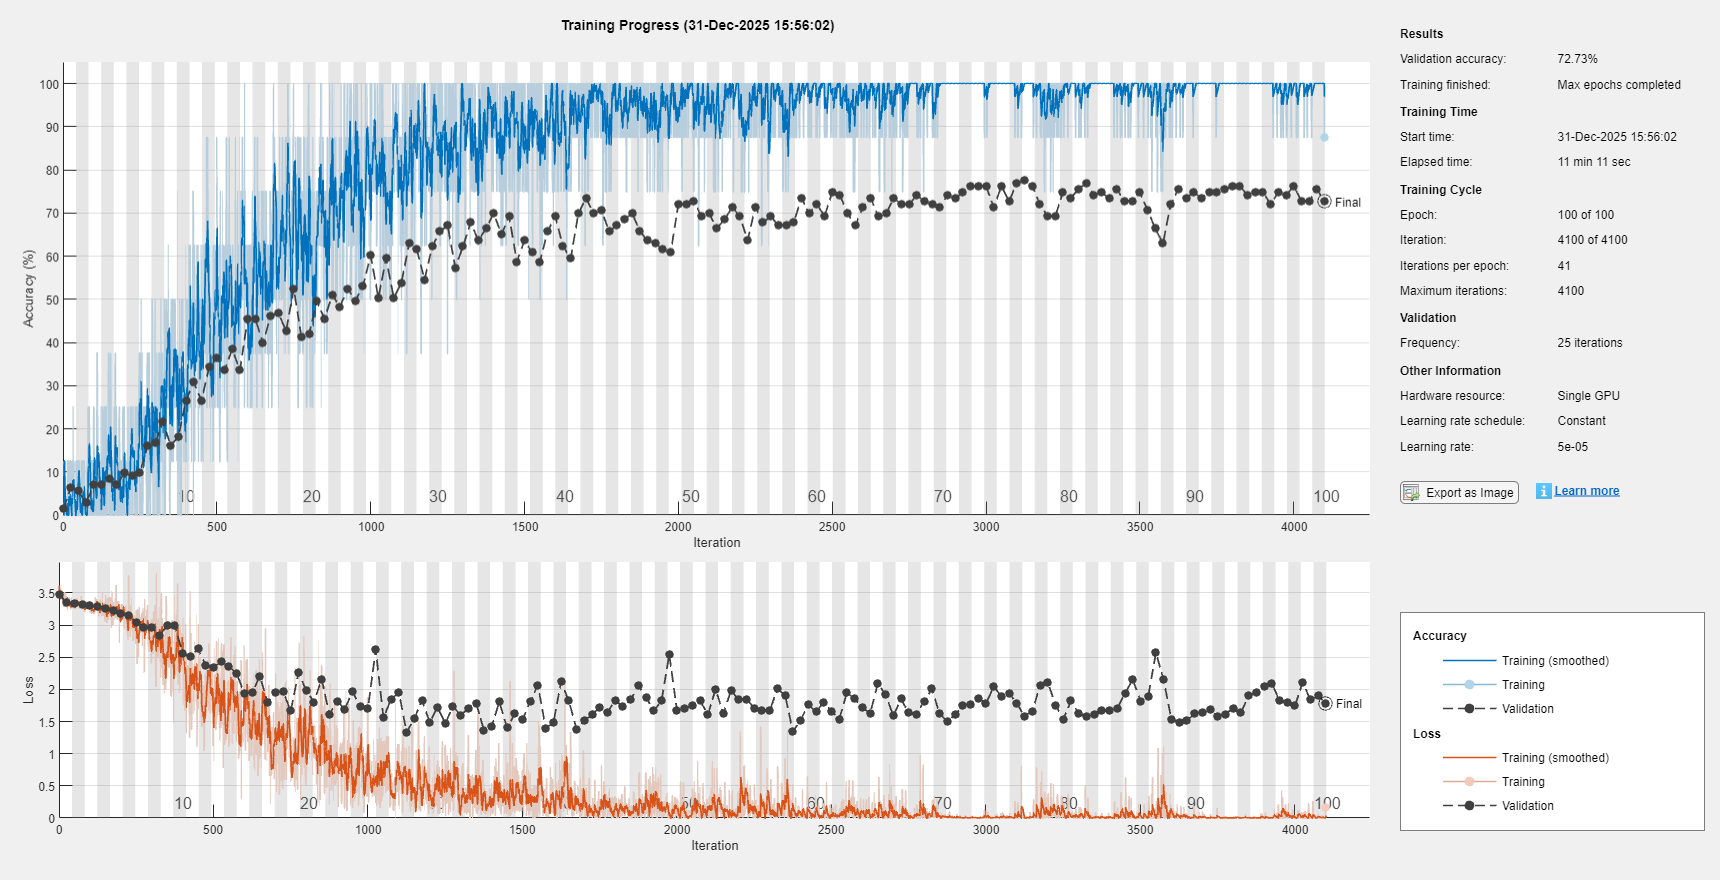

[net, traininfo] = trainNetwork(dsTrain,lgraph,opts);

save('FinalModel.mat', 'net');

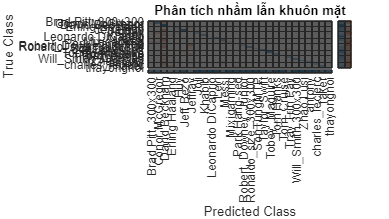

% 1. Dự đoán nhãn cho tập Validation
[YPred, scores] = classify(net, augVal);
YValidation = imdsVal.Labels;

% 2. Vẽ Confusion Matrix dạng bảng lớn
figure('Units', 'normalized', 'Position', [0.2 0.2 0.5 0.5]);
cm = confusionchart(YValidation, YPred);
cm.Title = 'Phân tích nhầm lẫn khuôn mặt';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';


% 3. Tìm ra top các nhãn bị sai nhiều nhất
errors = (YPred ~= YValidation);
wrongLabels = YValidation(errors);
uniqueWrong = unique(wrongLabels);
fprintf('\nDANH SÁCH NHÃN BỊ SAI NHIỀU NHẤT:\n');


DANH SÁCH NHÃN BỊ SAI NHIỀU NHẤT:


for i = 1:numel(uniqueWrong)
    count = sum(wrongLabels == uniqueWrong(i));
    fprintf('- Nhãn "%s": Sai %d lần\n', uniqueWrong(i), count);
end

- Nhãn "Brad Pitt_300x300": Sai 5 lần
- Nhãn "Conor McGregor": Sai 5 lần
- Nhãn "Erling Haaland": Sai 6 lần
- Nhãn "Huy": Sai 1 lần
- Nhãn "Jeff Bezo": Sai 7 lần
- Nhãn "Jeffray": Sai 1 lần
- Nhãn "Joji": Sai 7 lần
- Nhãn "Khabib": Sai 5 lần
- Nhãn "Levi": Sai 6 lần
- Nhãn "Messi": Sai 6 lần
- Nhãn "Mixigaming": Sai 9 lần
- Nhãn "Park Hang-seo": Sai 3 lần
- Nhãn "Robert_Downey_Junior": Sai 9 lần
- Nhãn "Ronaldo_size_300x300": Sai 6 lần
- Nhãn "SonTungMTP": Sai 4 lần
- Nhãn "Taylor_Swift": Sai 4 lần
- Nhãn "Tobey_Maguire": Sai 3 lần
- Nhãn "Tom Hanks": Sai 6 lần
- Nhãn "Tom_Cruise": Sai 7 lần
- Nhãn "Trây Trín Pảy": Sai 2 lần
- Nhãn "Will_Smith 300x300": Sai 5 lần
- Nhãn "Zhao Lusi": Sai 5 lần
- Nhãn "antony": Sai 7 lần
- Nhãn "charles_leclerc": Sai 6 lần
- Nhãn "faker": Sai 5 lần
- Nhãn "thayongnoi": Sai 5 lần


# **Kiểm tra ảnh**

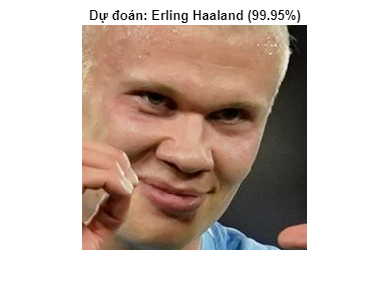

Mạng dự đoán đây là: Erling Haaland với độ tự tin 99.95%


%% SECTION 4: TEST ẢNH BẤT KỲ (Predict New Image)
% Đảm bảo bạn đã Export 'net' từ App ra Workspace trước khi chạy

% 1. Chọn file ảnh từ máy tính
[file, path] = uigetfile({'*.jpg;*.png;*.bmp', 'Image Files'}, 'Chọn ảnh khuôn mặt để kiểm tra');
if isequal(file,0)
    disp('Bạn đã hủy chọn ảnh.');
else
    fullPath = fullfile(path, file);
    img = imread(fullPath);
    
    % 2. Tiền xử lý ảnh (Cực kỳ quan trọng để khớp với SqueezeNet)
    % Cắt mặt nếu ảnh chưa được cắt (tùy chọn nhưng nên làm)
    faceDetector = vision.CascadeObjectDetector();
    bbox = faceDetector(img);
    if ~isempty(bbox)
        [~, maxIdx] = max(bbox(:,3));
        imgTest = imcrop(img, bbox(maxIdx, :));
    else
        imgTest = img; % Nếu không tìm thấy mặt thì dùng ảnh gốc
    end
    
    % Chuẩn hóa kích thước và kênh màu
    imgTest = imresize(imgTest, [227 227]);
    if size(imgTest, 3) == 1
        imgTest = cat(3, imgTest, imgTest, imgTest);
    end
    
    % 3. Dự đoán
    [label, scores] = classify(net, imgTest);
    accuracy = max(scores) * 100; % Độ tự tin cao nhất
    
    % 4. Hiển thị kết quả
    figure;
    imshow(imgTest);
    title(sprintf('Dự đoán: %s (%.2f%%)', char(label), accuracy));
    fprintf('Mạng dự đoán đây là: %s với độ tự tin %.2f%%\n', char(label), accuracy);
end